# **Object Detection with Deep Learning (Onramp)**

Usando o *Deep Learning* de uma rede neural e conceitos de *Computer Vision* e *Image Processing*, cria-se um detector de objetos poderoso

**Trabalha-se com uma interseção de *****Deep Learning *****e *****Computer Vision*****.**

#### 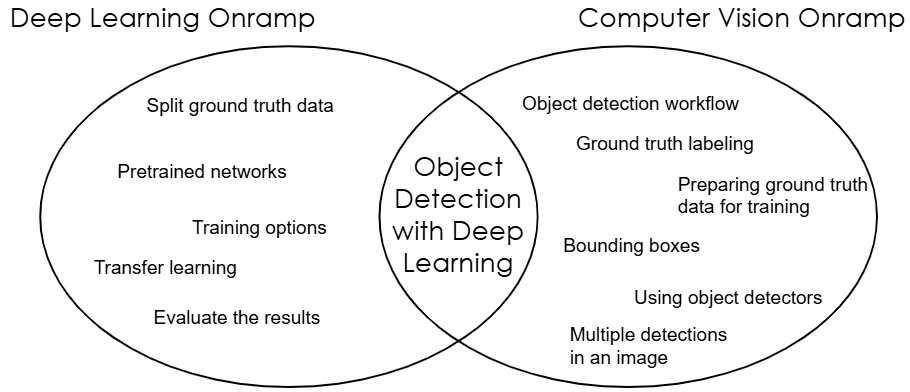

#### Detetores YOLOX pre-treinados

Usaremos as redes neurais de deep learning *You Only Look Once X* para criar um detector que balanceia rapidez e precisão. O *YOLOX* vem depois das versões 1 a 5.

A função `yoloxObjectDetector(baseNetwork)` cria um detector de objeto pré-treinado. A rede base (*backbone*) pode diferir em tamanho, tendo um diferente número de filtros e camadas convolucionais. Detectores baseados em redes menores detectam mais rápido.

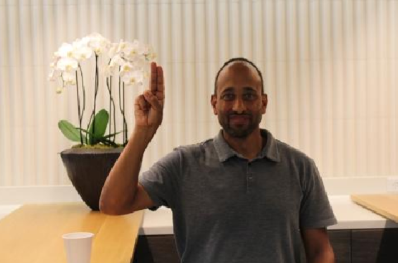

Usaremos como base um homem fazendo U em libras

manU = imread("manSigningU.jpg"); %Imagem acima
imshow(manU)

detector = yoloxObjectDetector("tiny-coco")

O que vai na entrada do `yoloxObjectDetector `pode ser também uma das opções:

- `yolox-tiny` mais leve, rápida e menos precisa

- `yolox-s/m/l` mais precisos, porém mais lentos

Tais redes variam no *número de camadas convolucionais, número de filtros *e *tamanho do modelo*. O exemplo do *tiny-coco* indica que *tiny* vem de `yolo-tiny`. Já o *coco* é o *dataset* de treinamento, no caso, é o **COCO** (Commom Objects in Context).

Um detector treinado possui uma propriedade chamada `ClassNames`, a qual lista as classes que pode detectar. Ela pode ser chamada pela operação `.ClassNames` após o nome do detector.

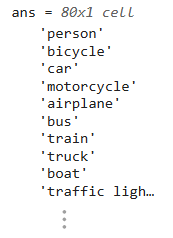

Tal detector pode atuar usando a função `detect(d,im) = [bbox, score, label]` da mesma forma que acontecia na *Computer Vision.*

[dbox,dscore,dlabel] = detect(detector,manU)

detectedIm = insertObjectAnnotation(manU,"rectangle",dbox,dlabel);
imshow(detectedIm); %Imagem com o que foi detectado

De forma similar, o resultado são vetores com as *bounding boxes*, *scores* de confiança e *rótulos*, agora delimitados pelo YOLO.

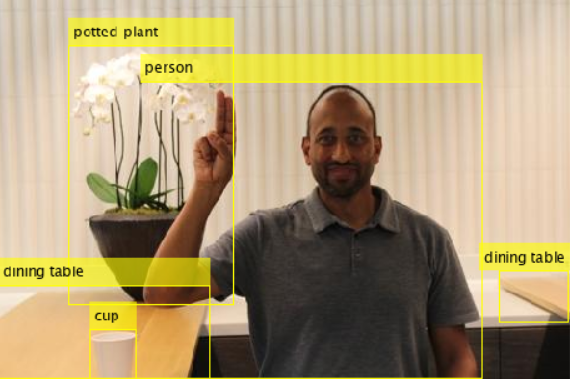

Detecção usando `tiny-coco`

Note que o detector não viu o U que queríamos. Usaremos *transfer learning *para que reconheça novas classes, ou seja, começaremos com um novo modelo pré-treinado e ajustaremos-no para reconhecer as letras. 

Usaremos o `nano-coco` que possui ainda menos dados que `tiny-coco`. Tal transferência é boa para projetos com limitação de hardware e em tempo real. Ele detecta menos objetos, como visto abaixo.

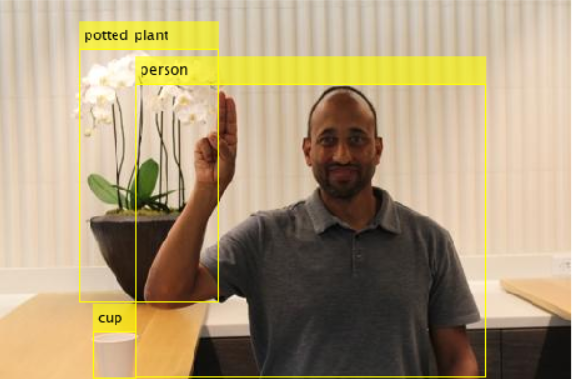

Detecção usando `nano-coco`

#### Preparação de Ground Truth Material

Com o uso do Image Labeler App, é possível gerar matrizes que contém a imagem, label e localização. 

`[imds,bxds] = objectDetectorTrainingData(gTruth);`

load /CourseData/aslVowels.mat gTruthVowels
gTruthVowels
gTruthVowels.LabelData

[imds,bxds] = objectDetectorTrainingData(gTruthVowels); 
%Transfere o GTD para transfer learning

cts = countEachLabel(bxds) 
%Conta quantos exemplos há de cada para ver se está balanceado

Agora combinaremos a lista de imagens e rótulos de caixa

gtData = combine(imds,bxds);
data = read(gtData)

%Extração dos dados
im = data{1}
bb = data{2}
lab = data{3}

%Visualização dos dados
imLabeled = insertObjectAnnotation(im,"rectangle",bb,lab)
imshow(imLabeled)

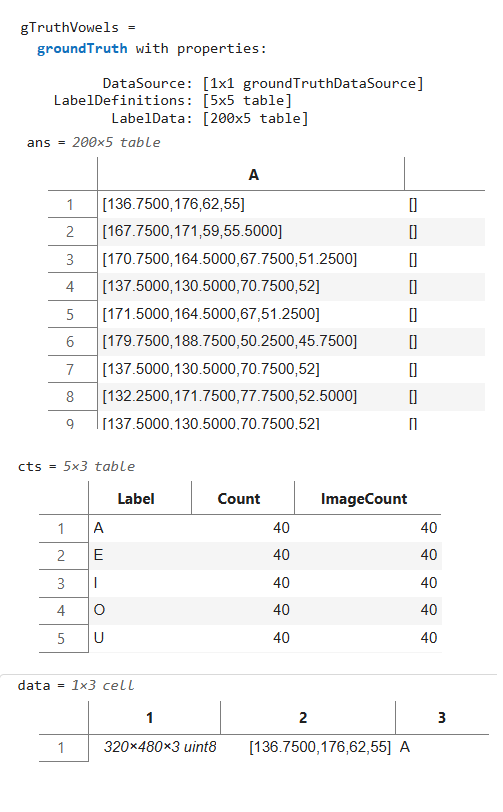

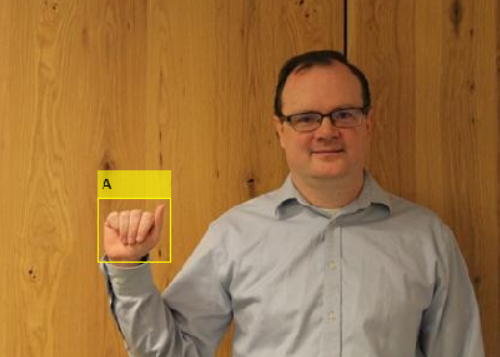

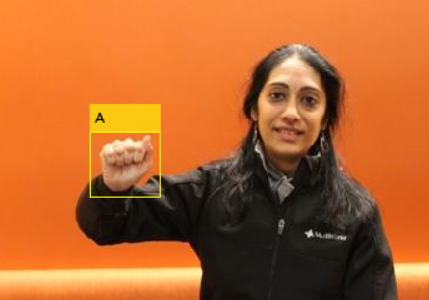

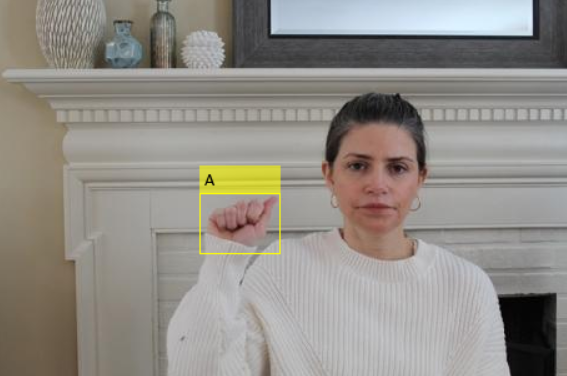

Ao repetir o `read(gtData)`, a imagem vai mudando e ciclando

#### Tipos de dados

Podemos separar os dados entre dados de Treinamento, Validação e Teste. 

A saída do `countEachLabel `é igual. Para selecionarmos um conjunto amostral aleatório, pode-se usar o `shuffle(ds)`.

load /CourseData/aslVowels.mat gTruthVowels
[imds,bxds] = objectDetectorTrainingData(gTruthVowels);
gtData = combine(imds,bxds);
countEachLabel(bxds)

gtShuffled = shuffle(gtData)

Vamos calcular o número de arquivos no datastore com o `numpartitions`. 

`n = numpartitions(ds)`

`n70percent = n*0.7`

numFiles = numpartitions(gtData)
numTrain = numFiles*0.7
numVal = numFiles*0.1

Escolhemos `numTrain` para ser 70% do número de partições e 10% para validação.

Podemos usar `subset `para indexar um *datastore*. Nesse caso, faremos um novo datastore de *Training Dataset* com os primeiros *numTrain* elementos de *gtShuffled*

gtTrain = subset(gtShuffled,1:numTrain)

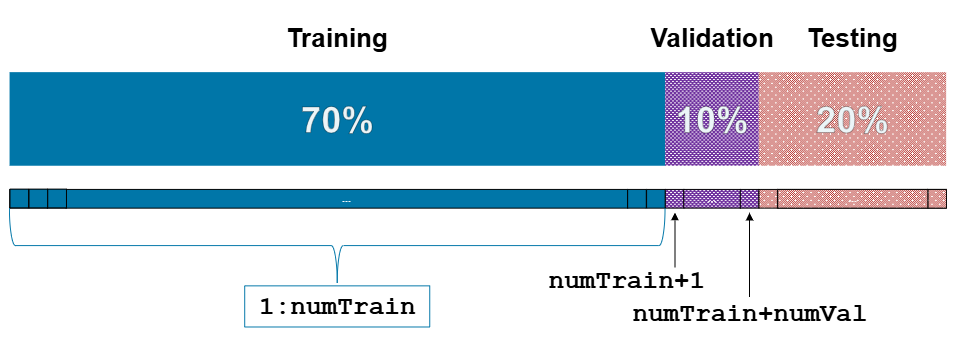

gtVal = subset(gtShuffled,numTrain+1:numTrain+numVal)
gtTest = subset(gtShuffled,numTrain+numVal+1:numFiles)

Será que o *training set* tem exemplos de cada classe? Pode-se usar o `countEachLabel` para cada classe no set:

`bx = ds.UnderlyingDatastores{2}`

`cts = countEachLabel(bx)`

b1 = gtTrain.UnderlyingDatastores{2}
trainCounts = countEachLabel(b1)

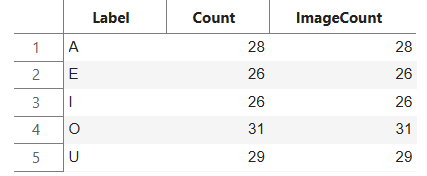

Caso a porcentagem de `numFiles` não seja inteiro, pode-se usar a função `floor` para torná-los inteiros.

#### Treinar e Usar um Detetor: Definindo os objetos de treino

Chamamos a função que cria um YOLOX pré-treinado e implementamos novas classes:

`d = yoloxObjectDetector(baseNetwork,classes,InputSize=[height width numChannels]);`

load validationData.mat gtVal

detector = yoloxObjectDetector("tiny-coco",["A" "E" "I" "O" "U"],...
InputSize=[224 224 3])


É possível determinar opções para o *transfer learning*. 

`opt = trainingOptions(solver)`

Como exemplo, o "adam" solver é feito para resolver problemas com ajustes minimos. Pode-se adicionar parâmetros como `MaxEpochs `e `MiniBatchSize. `O primeiro define as *épocas*, ou seja, quantos passes sobre o conjunto de dados o treino vai ter.Já quantos dados por vez são usados é o segundo.

options = trainingOptions("adam")
options = trainingOptions("adam",MiniBatchSize=70,MaxEpochs=10)

%Outro tipo
opt = trainingOptions("sgdm", MaxEpochs=15, MiniBatchSize=70, ...
    InitialLearnRate=0.001, Shuffle="every-epoch", Verbose=true);

O outro tipo usa o **Stochastic Gradient Descent with Momentum**, com 15 épocas, 70 imagens por *mini-batch*, taxa inicial de aprendizado de 0.001 e embaralhamento de dados a cada época. (Jesus)

Vamos especificar o conjunto de dados de validação

options = trainingOptions("adam",MiniBatchSize=70,MaxEpochs=10,...
ValidationData=gtVal,ValidationFrequency=2,Plots="training-progress")

Nesse caso, a cada 2 iterações ocorre uma validação, usando `gtVal` como parte dos dados de validação. Já o `Plots` cria um gráfico de progresso com acurácia.

**Obs. **No nosso caso, definimos manualmente as classes, porém é possível acessá-las diretamente de `gTruth` pelo comando:

classes = gTruthVowels.LabelDefinitions.Name;

Onde `LabelDefinitions` e `Name` são propriedades da variável `gTruthVowels`.

load /CourseData/aslVowels.mat gTruthVowels
classes = gTruthVowels.LabelDefinitions.Name;
disp(classes)

detector = yoloxObjectDetector("tiny-coco", classes, ...
InputSize=[224 224 3]);

Mostra na saída as classes.

#### Treinar e Usar um Detetor: Treinando o detetor

Temos a base de opcionar o detetor:

% create ground truth datastore
load /CourseData/aslVowels.mat gTruthVowels
[imds,bxds] = objectDetectorTrainingData(gTruthVowels);
gtData = combine(imds,bxds);

% split data into training, validation, and testing sets
gtShuffled = shuffle(gtData);
numFiles = numpartitions(gtShuffled);
numTraining = floor(numFiles*0.7);
gtTrain = subset(gtShuffled,1:numTraining);
numValidation = floor(numFiles*0.1);
gtVal = subset(gtShuffled,(numTraining+1):(numTraining+numValidation));

% create small, toy dataset
gtToy = subset(gtTrain,1:10)

% define variables required for training
detector = yoloxObjectDetector("tiny-coco", ...
    ["A" "E" "I" "O" "U"], ...
    InputSize=[224 224 3]);
optionsToy = trainingOptions("adam", ...
    MaxEpochs=1);
options = trainingOptions("adam", ...
    MiniBatchSize=70, ...      % 2 iterations per epoch
    MaxEpochs=10, ...
    ValidationData=gtVal, ...
    ValidationFrequency=2, ... % need to specify or it is every 
    % 50 iterations
    Plots="training-progress") % shows up after 1 epoch

Treinamos o detetor pela função

`trainedDet = trainYOLOXObjectDetector(gt,pretrainedDetector,options4train);`

aslDetectorToy = trainYOLOXObjectDetector(gtToy,detector,optionsToy);

Na prática, um detetor com poucos dados GTD e uma só época tem performance pobre. Um mais robusto é obtido ao mudar as opções:

aslDetectorToy = trainYOLOXObjectDetector(gtTrain,detector,options);

Pode-se guardar o tempo de execução do código usando a estrutura `tic-toc. tic` inicia o cronômetro em uma linha, `toc` o finaliza.

#### Treinar e Usar um Detetor: Detectando objetos com o Detetor Treinado

load /CourseData/aslDetector_allTrainingData10Epochs.mat
manA = imread("manSigningA.jpg");

[dbox,dscore,dlabel] = detect(aslDetector,manA)

detectedIm = insertObjectAnnotation(manA,"rectangle",dbox,dlabel);
imshow(detectedIm)
title("The Letter A")

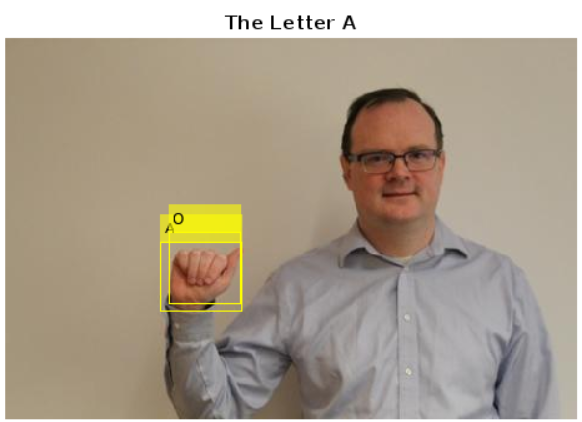

Porém o detetor apresenta ambiguidade quanto à detecção, notando tanto a letra A quanto a letra O no sinal, ambos com uma certa confiança. Usamos em `detect` o parâmetro `Threshold` para filtrar detecções de baixa confiança, da mesma forma que na *Computer Vision*.

Pode-se rodar um detetor em um *ground truth data set*, usando `detectionsGT = detect(detector,gt)`. O output é uma tabela com variáveis contendo as bboxes, scores e labels para cada imagem.

% Deteção filtrada
[dbox,dscore,dlabel] = detect(aslDetector,manA,Threshold=0.75) 

% Deteção rodada em um gt
results = detect(aslDetector,gtTest)

#### Avaliação de um Objeto Detectado: Detecção certa ou errada?

Para uma detecção de objeto, podem haver situações quanto à validação da mesma

- *True Positive* se a detecção acerta no rótulo e na posição do objeto.

- *False Negative *ou *Missed Detection* se há um erro em algum dos dois, especificamente se detectar o objeto, mas errar sua localização, ou se acertar a localização e errar o objeto detectado.

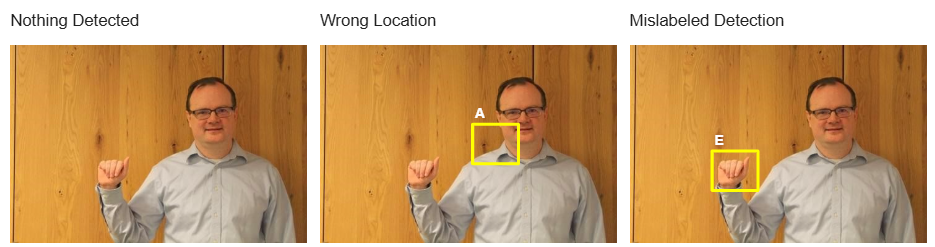

- *False Positive* ocorre quando há detecção de um objeto, mas que não está na localização acusada. O detector pode achar uma letra onde não há ou acusar a letra errada.

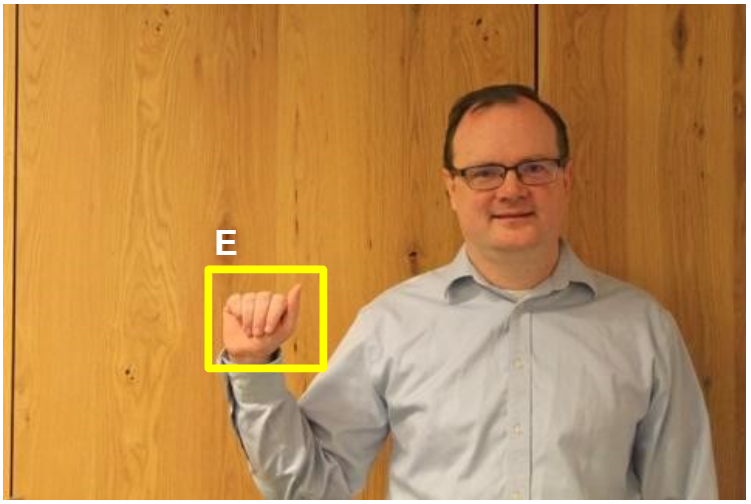

- No caso da figura acima, ocorre um *falso positivo *para a letra *E* e um falso negativo para a letra *A*.

A **localização **de um objeto detectado pode possuir um erro em relação a um ideal. Usamos a interseção sobre a união (**IoU**) para medir a qualidade do tamanho e da localização da *bbox*.

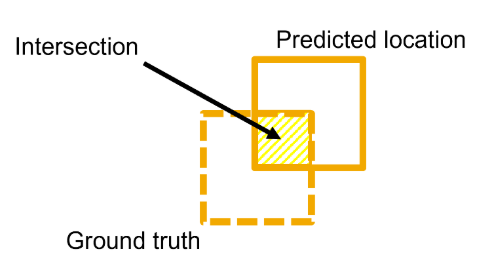


$$Q=\frac{\left(\mathrm{Predicted}\;\mathrm{Location}\right)\cap \left(\mathrm{Ground}\;\mathrm{Truth}\right)}{\;\left(\mathrm{Predicted}\;\mathrm{Location}\right)\cup \left(\mathrm{Ground}\;\mathrm{Truth}\right)}$$


O **IoU **pode ser usado comparativamente para estabelecer um limite e detectar *falsos positivos *e *positivos verdadeiros*. 

A **Matriz de confusão** indica a quantidade de detecções corretas e incorretas. As suas linhas representam *true classes* e as colunas *predicted classes*. 

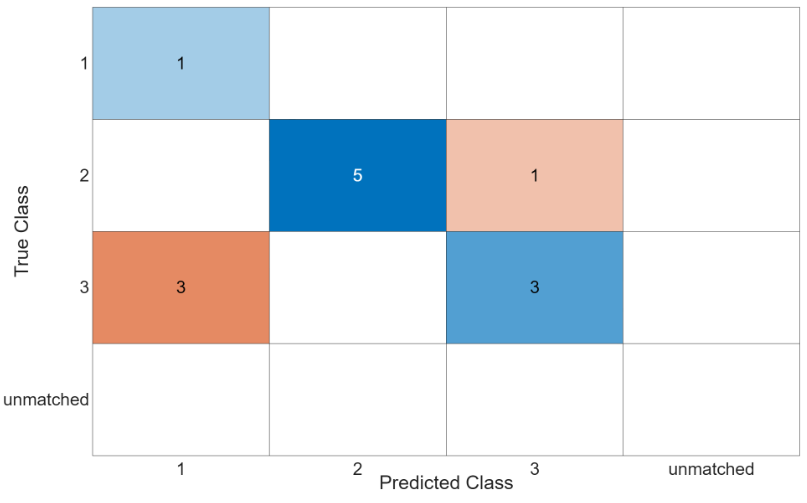

Os valores na diagonal principal são predições corretas do detector, com a sua quantidade. Já os que estão fora da diagonal são detecções erradas. 

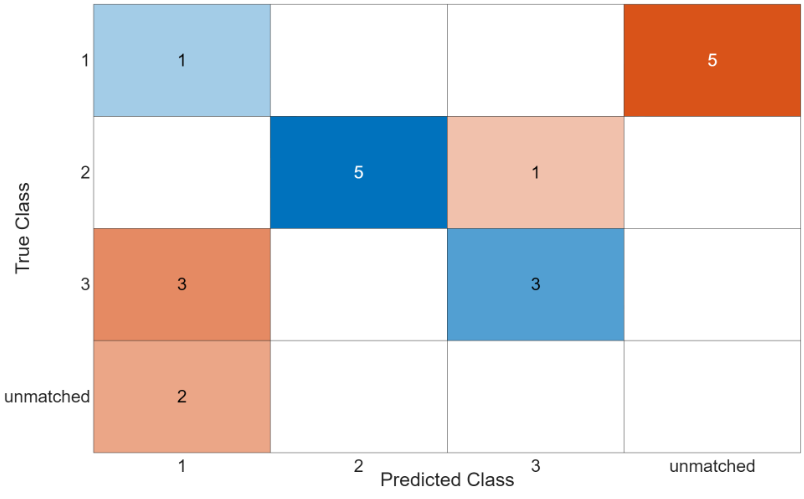

A última linha representa detecções que não correspondem a nenhum dos exemplos com *gt*. São detectados dois objetos da classe 1 onde não há nada. Já a última coluna representa exemplos onde não são detectados elementos que pertencem às classes. No caso, cinco vezes não há detecção de elementos da primeira classe.

A matriz mostra como um detetor performa com cada classe. Do exemplo, ele detecta bem elementos da segunda classe, mas apresenta erros quanto à primeira.

# *** avaliação de objeto por fazer ***

#### Augmentação de Dados

É bem possível que um conjunto de dados de treino não seja completo o bastante para treinar um algoritmo de máquina. Se introduzem alguns *vieses *por problemas como falta de diversidade dos dados, posição de câmera, orientação dos objetos, desfoque e iluminação. Alguns desses problemas requerem mais dados, porém outros podem ser sinteticamente formados por ***data augmentation***.

Augmentações são mudanças sintéticas nas imagens do conjunto de treino, como inserção de rotações, aumentos, recortes, translação, inversão, mudança de brilho, contraste e saturação, etc.

...
[imds,bxds] = objectDetectorTrainingData(gTruthVowels);
gtData = combine(imds,bxds);

data = read(gtData)
im = data{1};
bbox = data{2}
label = data{3}
annotatedImage = insertObjectAnnotation(im,"rectangle",bbox,label);
imshow(annotatedImage)

Em geral, imagens espelhadas não são bem interpretadas pelo detector, podendo causar problemas. A função `randomAffine2d `é uma função que cria uma transformação aleatória. Usar `xReflection = true` como entrada única cria transformações que ou refletem a imagem horizontalmente ou não fazem nada. Aplica-se a transformação fazendo:

`reflection = randomAffine2d(xReflection = true);`

`imTransformed = imwarp(image,reflection);`

tform = randomAffine2d(XReflection=true);
augmentedImage = imwarp(im,tform);
imshow(augmentedImage);

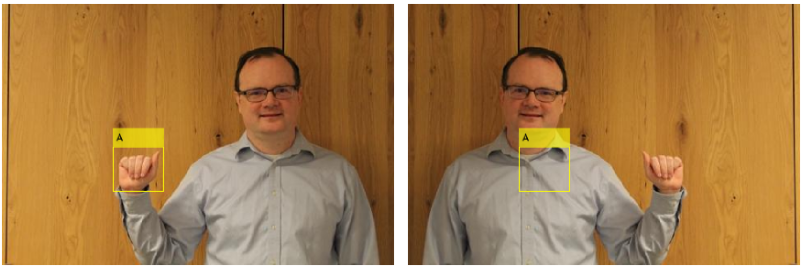

É bem possível que a posição da *bounding box *fique errada na imagem espelhada. É preciso transformar também as suas posições. Isso é feito em dois passos, 1) Criar uma referência espacial e 2) Usar a referência e a transformação para mudar a posição das caixas. Fazemos isso com:

`spatialReference = affineOutputView(transformedImageSize, transformation);`

`bboxTransformed = bboxwarp(bbox, transformation, SpatialReference);`

spatialRef = affineOutputView(size(augmentedImage),tform);
augmentedBoxes = bboxwarp(bbox,tform,spatialRef);

Para casos mais complicados, veja [https://www.mathworks.com/help/deeplearning/ug/bounding-box-augmentation-using-computer-vision-toolbox.html.](https://www.mathworks.com/help/deeplearning/ug/bounding-box-augmentation-using-computer-vision-toolbox.html.) 

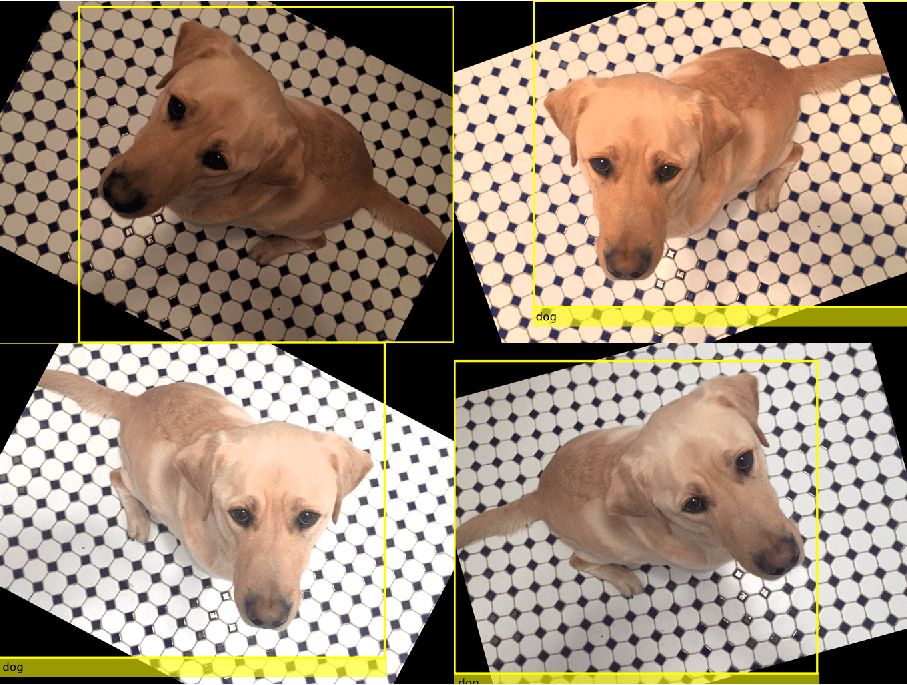

Cachorro Au-gmentado

Para aplicar aumentação de dados durante o treino, o algoritmo deve ser convertido em uma função capaz de receber o output da função `read`, que é usada para ler o ground truth data. É esperado que os dados estejam no formato `{image, bboxes, labels}`

out = {augmentedImage, augmentedBoxes, label}

Uma função pode ser declarada pelo corpo:

`function output = functionName(input)`

`%function body`

`end`

function out = flipAug(data)

% parse data read from datastore
im = data{1};
bbox = data{2};
label = data{3};
% create transform that flips images horizontally
tform = randomAffine2d(XReflection=true);
% warp image with random flip
augmentedImage = imwarp(im,tform);
% create spacial refernce for transform
spatialRef = affineOutputView(size(augmentedImage),tform);
% warp bounding boxes with random flip
augmentedBoxes = bboxwarp(bbox,tform,spatialRef);

% TASK 1: combine images, bounding boxes and labels
out = {augmentedImage, augmentedBoxes, label}

end

dataAug = flipAug(data)

Os novos dados representados pelo `dataAug `possuem maior variabilidade para treinar a inteligência. Após rodar algumas vezes, a imagem aparece espelhada:

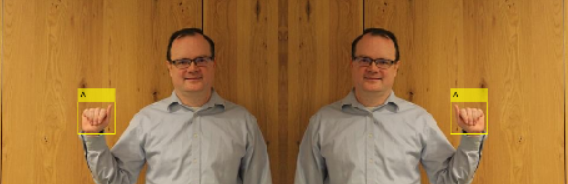

#### Aumentando o Ground Truth Data

% prepare ground truth data
load /CourseData/aslVowels.mat gTruthVowels
[imds,bxds] = objectDetectorTrainingData(gTruthVowels);
gtData = combine(imds,bxds);

% split images into training, validation, and testing
gtShuffled = shuffle(gtData);
numFiles = numpartitions(gtShuffled);
numTraining = floor(numFiles*0.7);
gtTrain = subset(gtShuffled, 1:numTraining);
numValidation = floor(numFiles*0.1);
gtVal = subset(gtShuffled, (numTraining+1):(numTraining + numValidation));

Tome junto o código da função de aumento anterior.

Para inserir o aumento no treino, ele deve ser aplicado no conjunto de treino e no de validação. Para transformar um conjunto de dados, usa-se:

`dsTransformed = transform(ds, @functionName)`

gtTrainAug = transform(gtTrain,@flipAug)

dataAug = read(gtTrainAug)
imAug = dataAug{1};
bboxAug = dataAug{2};
label = dataAug{3};
annotatedImageAug = insertObjectAnnotation(imAug,"rectangle",bboxAug,label);
imshow(annotatedImageAug)

gtValAug = transform(gtVal,@flipAug)

**Efetividade do Aumento**

load /CourseData/aslDetectorMaxEp100 aslDetector
load /CourseData/aslDetectorMaxEp100_withAugmentation aslDetector_withAugmentation 
load groundTruthVars.mat gtData gtTest gTruthVowels gtLeftSigning gtTest_LeftSigning

O código a seguir leva em consideração dados aumentados e não aumentados. 

`gtLeftSigning` é o GTD espelhado.

detectorToEvaluate = aslDetector; %Sem aumento
groundTruthToEvaluate = gtLeftSigning;
results = detect(detectorToEvaluate,groundTruthToEvaluate, ...
    Threshold=0.4);
metrics = evaluateObjectDetection(results, ...
    groundTruthToEvaluate);
[confMat,confLabels] = confusionMatrix(metrics);
confusionchart(confMat{1},confLabels)

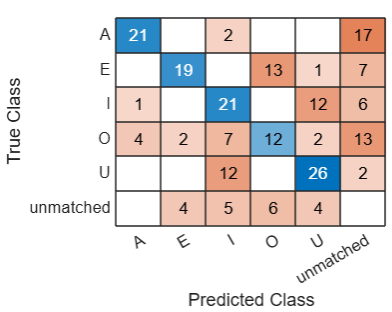

detectorToEvaluate = aslDetector_withAugmentation; %Com aumento
groundTruthToEvaluate = gtLeftSigning; 
results = detect(detectorToEvaluate,groundTruthToEvaluate, ...
    Threshold=0.4);
metrics = evaluateObjectDetection(results, ...
    groundTruthToEvaluate);
[confMat,confLabels] = confusionMatrix(metrics);
confusionchart(confMat{1},confLabels)

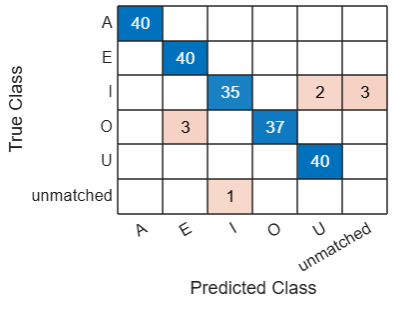

Ocorre uma correção absurda com o uso do aumento.

- Usando `gtTest` e sem aumento obtemos:

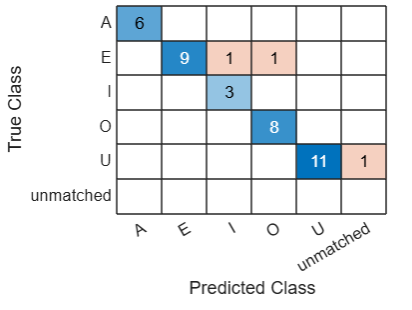

- Usando `gtTest` e com aumento: